# Module 2: Localization

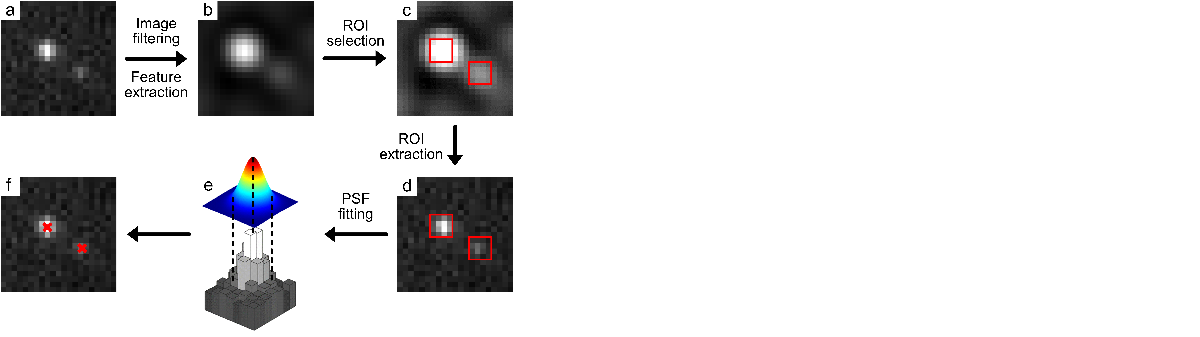

Localization is the main computational effort in any SMLM data analysis, as it is the process of extracting localizations (i.e. frame, x, y data) from raw data.

## Identification of regions of interest with Difference-of-Gaussian filtering

First, we load the data and show a representative frame of the temporally-filtered movie that was the output from Module 1. Individual emitters are clearly present in this frame.

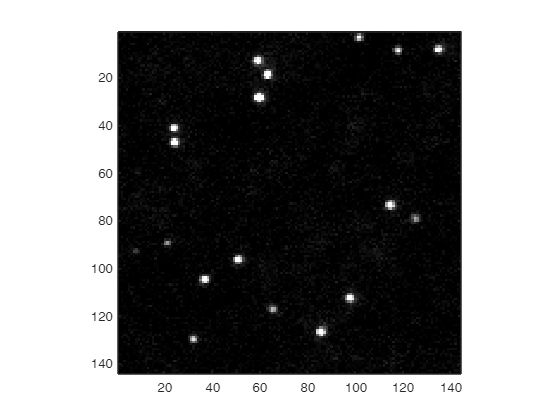

%Load an example movie - TIFF movie loading in MATLAB is somewhat involved.
%We first need to get information about the size of the image stack via
%imfinfo, then read the data frame-by-frame with imread.
%We load the data that is the output of the previous module temporal median
%filter
im_info = imfinfo('Data\DNAPAINT_substack_median_filtered.tif'); %Returns info about image
im = imread('Data\DNAPAINT_substack_median_filtered.tif', 1) ; % read in first frame
%Add each subsequent frame to the image
for ii = 2:size(im_info, 1)
    newframe = imread('Data\DNAPAINT_substack_median_filtered.tif', ii);
    im = cat(3 , im, newframe);
end
%Convert to double rather than uint16
im = double(im);

%First we read the data of a single frame to showcase this
singleFrame = im(:,:,31);
%We plot this image with a gray colormap and minimum and maximum colormap values to showcase the individual localizations
figure();
imagesc(singleFrame');
caxis([0 15000]);
colormap('gray');
axis square;

Next, we need to filter the image to find regions of interest (ROIs) where emitters reside

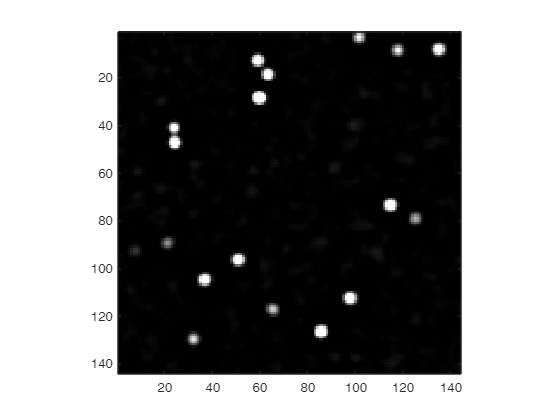

%The sigma of the Gaussian filters is specificied for the Difference-of-Gaussian filter
GaussFilterSigma1 = 1.5; %Sigma of the first Gaussian Filter (in pixels)
GaussFilterSigma2 = 4; %Sigma of the second Gaussian Filter (in pixels)

%We filter the image twice, with both sigma
%The images are converted to float value to ensure negative numbers during subtraction
Gauss1FilteredImage = imgaussfilt(singleFrame, GaussFilterSigma1);
Gauss2FilteredImage = imgaussfilt(singleFrame, GaussFilterSigma2);
%The difference of Gaussian is calculaed by subtracting the two images
DoGFilteredImage = Gauss1FilteredImage-Gauss2FilteredImage;

%We plot this image to show the filtered image
figure();
imagesc(DoGFilteredImage');
caxis([0 4000]);
colormap('gray');
axis square;

## Quantification of regions of interest via maximum finding

And now we can continue to actually find the ROIs, based on this filtered image.

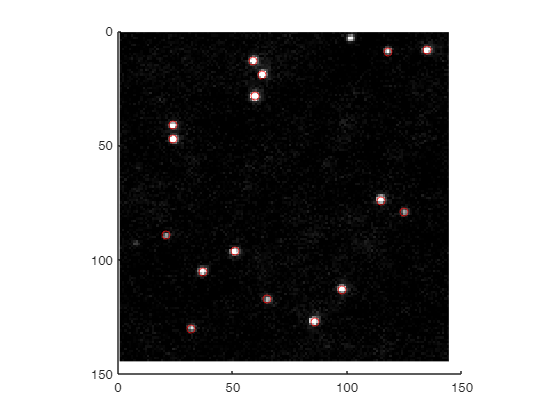

%Now we find the local maxima of this image to find where the emitters are in the frame
%First we specify the parameter on how high the value needs to be of the DoG-filtered image to count as local maximum
%Normally, this parameter is a multiple of the standard deviation (std) of the filtered image
LinearVersionDoGFilteredImage = reshape(DoGFilteredImage,size(DoGFilteredImage,1)*size(DoGFilteredImage,2),1);
% Try changing the value of the multiplication of the std, if it's too low,
% too many emitters will be found - if it's too high, not all emitters will
% be found.
% After changing this value, the figures below will update.
MinValueLocalMax = std(LinearVersionDoGFilteredImage)*1.8;

%We use the imregionalmax function to find the local peaks.
% This creates an 2D array of the same size as the image, with Boolean operators
% showing where the maxima are.
localpeaksImage = imregionalmax(DoGFilteredImage,8);
%Now we select only these localpeaks that correspond to a value higher than
%MinValueLocalMax
localpeaksImage = (DoGFilteredImage>MinValueLocalMax).*localpeaksImage;
%And finally we extract the row/column indeces of this 2D array
ind = find(localpeaksImage);
clear localpeaks
[localpeaks(:,1),localpeaks(:,2)] = ind2sub(size(localpeaksImage),ind);

%We have to filter out local peaks that are on the edge of the image,
%because extracting the ROI cannot happen there (and if we shift the ROI,
%the hypothesis that the emitter is approximately in the center of the ROI
%is wrong)

ROIradius = 3; %Radius for regions of interest (ROI) - total ROI will be (ROIradius*2+1)-by-(ROIradius*2+1)

%We loop through the localpeaks entry from back-to-front because we remove
%any 'wrong' entries
for i = size(localpeaks,1):-1:1
    %Test if this entry is closer than the ROIradius+1 from any edge
    if (localpeaks(i,1) <= ROIradius+1) || (localpeaks(i,1) >= size(singleFrame,1)-(ROIradius+1)) ...
            || (localpeaks(i,2) <= ROIradius+1) || (localpeaks(i,2) >= size(singleFrame,2)-(ROIradius+1))
        %Remove this entry
        localpeaks(i,:) = [];
    end
end

%Show the found local maxima on top of the original image
figure()
hold on
imagesc(singleFrame')
caxis([0 15000]);
set(gca,'YDir','Reverse')
axis square
colormap('gray');
scatter(localpeaks(:,1),localpeaks(:,2),'ro')

And we can use this data to extract just the ROIs

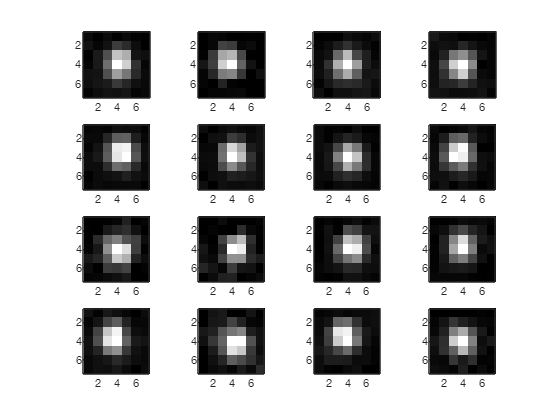

%Next, we isolate the areas around these individual emitters for fitting

%Prepare an image
figure()
%Calculate the number of subplots that will be drawn - based on how many peaks are found
subplotsize = ceil(sqrt(size(localpeaks,1)));

%Loop over all found localizations
for l = 1:size(localpeaks,1)
    %Extract the ROI - we know it is centered around the localpeaks[l,:] position, with radius ROIradius
    ROI = singleFrame(localpeaks(l,1)-ROIradius:localpeaks(l,1)+ROIradius,...
        localpeaks(l,2)-ROIradius:localpeaks(l,2)+ROIradius);
    %Show the ROIs in a subplot image
    subplot(subplotsize,subplotsize,l)
    imagesc(ROI);
    colormap('gray')
    axis square
end

## Sub-pixel PSF localization

Next, we localize the emitter's position with high accuracy in these ROIs

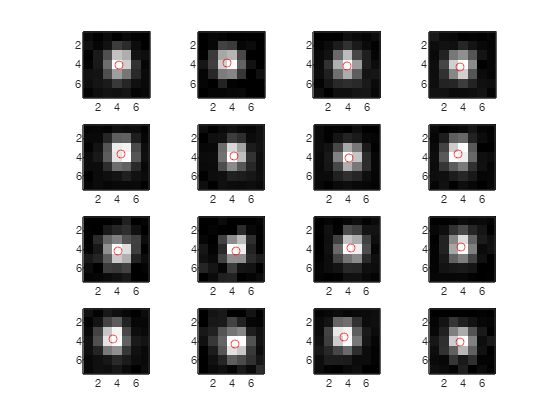

8.22 - 135.00
8.57 - 117.82
12.98 - 59.12
18.69 - 63.19
28.47 - 59.58
41.27 - 23.82
47.19 - 24.09
73.57 - 114.66
79.20 - 125.18
89.43 - 21.15
96.47 - 50.85
104.87 - 36.73
112.60 - 97.75
117.33 - 65.27
126.65 - 85.52
129.78 - 32.04


%Initialise a figure for showcasing the fits
figure()
%Now we perform phasor fitting on these subplots to get a sub-pixel location
%For the original phasor manuscript, see doi.org/10.1063/1.5005899 (Martens et al., 2017)
for l = 1:size(localpeaks,1)
    %Extract the ROI - we know it is centered around the localpeaks[l,:] position, with radius ROIradius
    ROI = singleFrame(localpeaks(l,1)-ROIradius:localpeaks(l,1)+ROIradius,...
        localpeaks(l,2)-ROIradius:localpeaks(l,2)+ROIradius);
    %Perform 2D Fourier transform over the complete ROI
    ROI_F = fft2(ROI);

    %We have to calculate the phase angle of array entries [0,1] and [1,0] for the sub-pixel x and y values, respectively
    %This phase angle can be calculated as follows:
    xangle = atan2(imag(ROI_F(1,2)),real(ROI_F(1,2)));
    %Correct in case it's positive
    if xangle > 0
        xangle = xangle-2*pi;
    end
    %Calculate position based on the ROI radius
    PositionX = abs(xangle)/(2*pi/(ROIradius*2+1))+1;

    %Do the same for the Y angle and position
    yangle = atan2(imag(ROI_F(2,1)),real(ROI_F(2,1)));
    if yangle > 0
        yangle = yangle-2*pi;
    end
    PositionY = abs(yangle)/(2*pi/(ROIradius*2+1))+1;

    %Get the final localization based on the ROI position
    LocalizationX = localpeaks(l,2)-1-ROIradius+PositionX;
    LocalizationY = localpeaks(l,1)-1-ROIradius+PositionY;

    %Print the list of localizations and make a plot of it
    fprintf('%.2f - %.2f\n',LocalizationX, LocalizationY);
    %Show the ROIs in a subplot image
    subplot(subplotsize,subplotsize,l);
    imagesc(ROI);
    colormap('gray');
    axis square
    hold on
    %Scatter the points
    scatter(PositionX,PositionY,'ro')
end

Next, we also want to extract an estimate for the intensity for further downstream analysis. An intensity measure is important for some of the drift correction routines.

For this, we use a photometry-based approach. Briefly, we assume that the pixels in the center of the single emitter ROI contribute to the emitter's intensity, while the pixels at the outer edges of the ROI contribute to the typical noise, and should be subtracted.

This computation is directly defined as function for better integration later on: photometry_intensity (hyperlink)** on line 258.**

For all ROIs, this intensity is calculated, and the images are sorted based on intensity as an output.

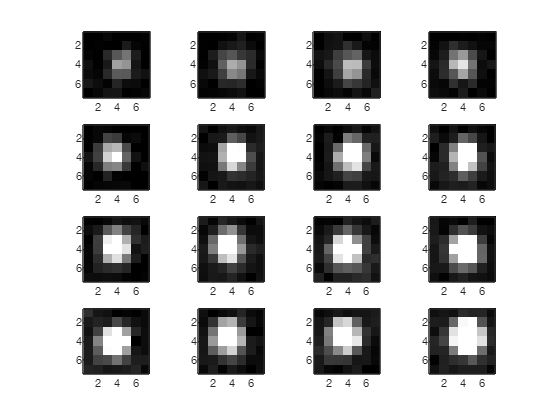

%To showcase that this works, we will sort the ROIs on intensity and show
%them in that order

%A variable is created that will store the localizations, and is initialized with zeros (to speed up code)
SignalIntensityArray = zeros(10000,2);

%We use the imregionalmax function to find the local peaks.
% This creates an 2D array of the same size as the image, with Boolean operators
% showing where the maxima are.
localpeaksImage = imregionalmax(DoGFilteredImage,8);
%Now we select only these localpeaks that correspond to a value higher than
%MinValueLocalMax
localpeaksImage = (DoGFilteredImage>MinValueLocalMax).*localpeaksImage;
%And finally we extract the row/column indeces of this 2D array
ind = find(localpeaksImage);
clear localpeaks
[localpeaks(:,1),localpeaks(:,2)] = ind2sub(size(localpeaksImage),ind);

%We loop through the localpeaks entry from back-to-front because we remove
%any 'wrong' entries
for i = size(localpeaks,1):-1:1
    %Test if this entry is closer than the ROIradius+1 from any edge
    if (localpeaks(i,1) <= ROIradius+1) || (localpeaks(i,1) >= size(singleFrame,1)-(ROIradius+1)) ...
            || (localpeaks(i,2) <= ROIradius+1) || (localpeaks(i,2) >= size(singleFrame,2)-(ROIradius+1))
        %Remove this entry
        localpeaks(i,:) = [];
    end
end


for l = 1:size(localpeaks,1)
    %Extract the ROI - we know it is centered around the localpeaks[l,:] position, with radius ROIradius
    ROI = singleFrame(localpeaks(l,1)-ROIradius:localpeaks(l,1)+ROIradius,...
        localpeaks(l,2)-ROIradius:localpeaks(l,2)+ROIradius);
    %Add its intensity to the array
    SignalIntensityArray(l,:) = [l,photometry_intensity(ROI)];
end

%Remove zero-entries
SignalIntensityArray = SignalIntensityArray(SignalIntensityArray(:,1)~=0,:);

%Sort the list
SignalIntensityArraySorted = sortrows(SignalIntensityArray,2);

%Initialise a figure...
figure()
% We loop over the length of the array in which we stored the signal intensity
for l = 1:size(SignalIntensityArraySorted)
    %We extract the ROI id from this array
    ROIid = SignalIntensityArraySorted(l,1);
    %And we extract the ROI corresponding to this ROIid
    ROI = singleFrame(localpeaks(ROIid,1)-ROIradius:localpeaks(ROIid,1)+ROIradius,...
        localpeaks(ROIid,2)-ROIradius:localpeaks(ROIid,2)+ROIradius);
    %Show the ROIs with standardized min and max values
    subplot(subplotsize,subplotsize,l)
    imagesc(ROI)
    colormap('gray')
    axis square
    caxis([0 15000])
end

## Using functions

Now we encapsulate all of this in a two functions: one for performing sub-pixel localization via phasor, which is called by the other function which extracts the ROIs from the image. The necessary variables are declared as input. The main function can then simply be called separately to find all localizations in a single frame.

**The function can be found on line 311 and is called **localization_singleImage

Now all functions are properly defined and described, meaning it can be applied to a single image. This will be done on the same frame as before. This process should of course be repeated for all frames in a movie (or a stack of images) in normal single-molecule analysis.

%Example of the function usage
out = localization_singleImage(singleFrame,1.5,4,2,3);

%Show all localizations
for i = 1:size(out,1)
fprintf('%.2f %.2f %.2f\n',out(i,:))
end

135.22 8.00 868561.38
117.57 8.82 522709.00
58.98 13.12 1038515.38
62.69 19.19 1084466.26
60.47 27.58 1345700.64
24.27 40.82 713250.98
24.19 47.09 1045790.62
114.57 73.66 1104327.00
125.20 79.18 348249.66
21.43 89.15 278322.00
51.47 95.85 737069.44
36.87 104.73 886271.98
97.60 112.75 983185.38
65.33 117.27 399881.00
85.65 126.52 1177229.00
31.78 130.04 489479.90


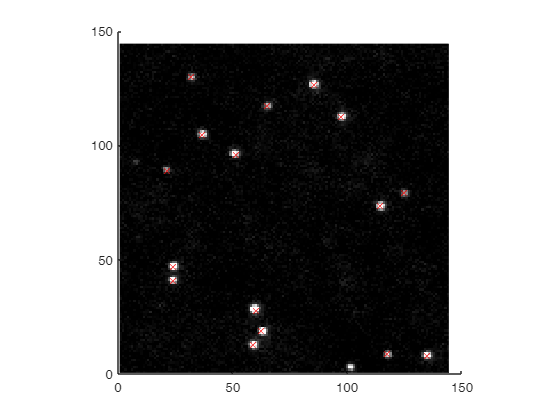

%Show the image with the found localizations
figure()
hold on
imagesc(singleFrame');
caxis([0 15000]);
colormap('gray')
axis square
for i = 1:size(out,1)
    scatter(out(i,1),out(i,2),'rx')
end

## Complete localization procedure

 The next step is to repeat this for all images in a movie (or image stack). This can easily be done by a single for-loop, as performed here. As an output, we show a single frame, but with localizations found in multiple frames.

%A variable is created that will store the localizations, and is initialized with zeros (to speed up code)
loclist = zeros(1000000,4);

%A counter is started
counter = 1;
%Loop over the frames in the movie
for frame = 1:size(im,3)
  %Perform localization on this frame
  out = localization_singleImage(im(:,:,frame),2.5,4,2,3);
  %Fill the loclist array with the [frame,x,y]-information
  loclist(counter:counter+size(out,1)-1,1) = frame;
  loclist(counter:counter+size(out,1)-1,2:4) = out;
  %Increase the counter by the size of the localizations on this frame
  counter = counter+size(out,1);
end

%Remove zero-entries
loclist = loclist((loclist(:,1) ~=0),:);

%Show info about the localization list
fprintf('Size of localization array:\n')

Size of localization array:


fprintf(num2str(size(loclist)));

1710     4

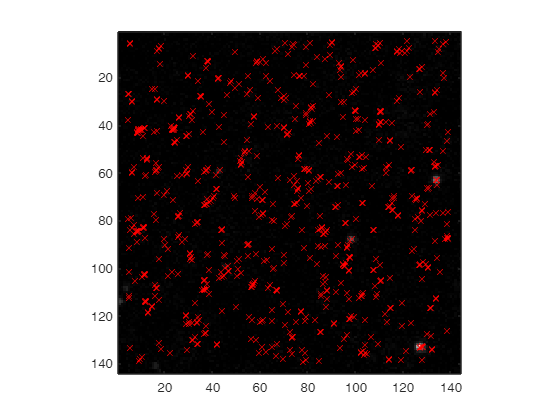


%Show all localizations
figure()
imagesc(im(:,:,1)');
colormap('gray')
axis square
hold on
scatter(loclist(:,2),loclist(:,3),'rx');

This localization information forms the basis of all downstream processing in single-molecule localization analysis. The exact algorithms normally are more complicated via for example more rigourous image filtering or better point-spread-function fitting functions. Nonetheless, the steps outlined here provide an accurate methodology for single-molecule localization.

## Function declaration

function SignalIntensity = photometry_intensity(ROI)
    %The intensity-measure we will use is a photometry-based method, described in:
    %S. Preus, L.L. Hildebrandt, and V. Birkedal, Biophys. J. 111, 1278 (2016).
    %Also see Figure S11 in doi.org/10.1063/1.5005899 (Martens et al., 2017)
    
    %First we create emtpy signal and background maps with the same shape as
    %the ROI.
    SignalMap = zeros(size(ROI));
    BackgroundMap = zeros(size(ROI));
    %Next we determine the ROI radius from the data
    ROIradius = (size(ROI,1)-1)/2;
    
    %Now we attribute every pixel in the signal and background maps to be
    %belonging either to signal or background based on the distance to the
    %center
    %For this, we loop over the x and y positions
    for xx = 1:size(ROI,1)
        for yy = 1:size(ROI,2)
            %Now we calculate Pythagoras' distance from this pixel to the center
            distToCenter = sqrt((xx-size(ROI,1)/2+.5)^2 + (yy-size(ROI,2)/2+.5)^2);
            %And we populate either SignalMap or BackgroundMap based on this distance
            if distToCenter <= (ROIradius) %This is signal for sure
                SignalMap(xx,yy) = 1;
            elseif distToCenter > (ROIradius-0.5) %This is background
                BackgroundMap(xx,yy) = 1;
            end
    
            %Now we take the 56th percentile of the data in the background map.
            %This is a valid measure for the expected background intensity
    
            %First we multiple the ROI intensity values with the background map
            %and reshape it to a 1D array
            BackgroundIntensityList = reshape((ROI*BackgroundMap),size(ROI,1)*size(ROI,2),1);
            %We also have to remove all the zeros in this list
            BackgroundIntensityList = BackgroundIntensityList(BackgroundIntensityList ~= 0);
            %And then we take the 56th percentile (or the value closest to it)
            BackgroundIntensity = prctile(BackgroundIntensityList,56);
    
            %To then assess the intensity, we simply sum the entire ROI in the SignalMap
            %and subtract the BackgroundIntensity for every pixel
            SignalIntensity = sum(sum(ROI*SignalMap));
            SignalIntensity = SignalIntensity-BackgroundIntensity*sum(sum(SignalMap));
    
            %And lastly, we prevent negative intensities
            SignalIntensity = max(SignalIntensity,0);
        end
    end
end




%Function for single image localization
function [localization_list] = ...
    localization_singleImage(imageData,GaussFilterSigma1,GaussFilterSigma2,MinValueLocalMaxStdMultiplier,ROIradius)
    %Difference-of-Gaussian filter
    %We filter the image twice, with both sigma
    %The images are converted to float value to ensure negative numbers during subtraction
    Gauss1FilteredImage = imgaussfilt(imageData, GaussFilterSigma1);
    Gauss2FilteredImage = imgaussfilt(imageData, GaussFilterSigma2);
    %The difference of Gaussian is calculaed by subtracting the two images
    DoGFilteredImage = Gauss1FilteredImage-Gauss2FilteredImage;
    
    %Now we find the local maxima of this image to find where the emitters are in the frame
    %First we specify the parameter on how high the value needs to be of the DoG-filtered image to count as local maximum
    %Normally, this parameter is a multiple of the standard deviation (std) of the filtered image
    LinearVersionDoGFilteredImage = reshape(DoGFilteredImage,size(DoGFilteredImage,1)*size(DoGFilteredImage,2),1);
    MinValueLocalMax = std(LinearVersionDoGFilteredImage)*MinValueLocalMaxStdMultiplier;
    
    %We use the imregionalmax function to find the local peaks.
    % This creates an 2D array of the same size as the image, with Boolean operators
    % showing where the maxima are.
    localpeaksImage = imregionalmax(DoGFilteredImage,8);
    %Now we select only these localpeaks that correspond to a value higher than
    %MinValueLocalMax
    localpeaksImage = (DoGFilteredImage>MinValueLocalMax).*localpeaksImage;
    %And finally we extract the row/column indeces of this 2D array
    ind = find(localpeaksImage);
    clear localpeaks
    [localpeaks(:,1),localpeaks(:,2)] = ind2sub(size(localpeaksImage),ind);
    
    %We loop through the localpeaks entry from back-to-front because we remove
    %any 'wrong' entries
    for i = size(localpeaks,1):-1:1
        %Test if this entry is closer than the ROIradius+1 from any edge
        if (localpeaks(i,1) <= ROIradius+1) || (localpeaks(i,1) >= size(imageData,1)-(ROIradius+1)) ...
                || (localpeaks(i,2) <= ROIradius+1) || (localpeaks(i,2) >= size(imageData,2)-(ROIradius+1))
            %Remove this entry
            localpeaks(i,:) = [];
        end
    end
    
    localization_list = zeros(size(localpeaks,1),3);
    for l = 1:size(localpeaks,1)
        %Extract the ROI - we know it is centered around the localpeaks[l,:] position, with radius ROIradius
        ROI = imageData(localpeaks(l,1)-ROIradius:localpeaks(l,1)+ROIradius,...
            localpeaks(l,2)-ROIradius:localpeaks(l,2)+ROIradius);
        %Get locations from phasor function - function is below
        [xpos,ypos,intensity]=phasor_fitting(ROI,ROIradius,[localpeaks(l,1),localpeaks(l,2)]);
        localization_list(l,:) = [xpos,ypos,intensity];
    end
    end
    
    
    
    
    %Function for phasor fitting
    function [LocalizationX, LocalizationY, SignalInt] = ...
        phasor_fitting(ROI,ROIradius,localpeak)
    %Obtain the intensity
    SignalInt = photometry_intensity(ROI);
    
    %Perform 2D Fourier transform over the complete ROI
    ROI_F = fft2(ROI);
    
    %We have to calculate the phase angle of array entries [0,1] and [1,0] for the sub-pixel x and y values, respectively
    %This phase angle can be calculated as follows:
    xangle = atan2(imag(ROI_F(1,2)),real(ROI_F(1,2)));
    %Correct in case it's positive
    if xangle > 0
        xangle = xangle-2*pi;
    end
    %Calculate position based on the ROI radius
    PositionX = abs(xangle)/(2*pi/(ROIradius*2+1))+1;
    
    %Do the same for the Y angle and position
    yangle = atan2(imag(ROI_F(2,1)),real(ROI_F(2,1)));
    if yangle > 0
        yangle = yangle-2*pi;
    end
    PositionY = abs(yangle)/(2*pi/(ROIradius*2+1))+1;
    
    %Get the final localization based on the ROI position
    LocalizationX = localpeak(1)-ROIradius-1+PositionX;
    LocalizationY = localpeak(2)-ROIradius-1+PositionY;
end